addpath('lab4files')
addpath('simfiles')
sec3 = load('ThetaData3')

sec3 = struct with fields:
    Average_Theta: [1×1 struct]
            Theta: [1×1 struct]


sec4_i = load('Psidotdata4cw')

sec4_i = struct with fields:
    Average_psi_dot: [1×1 struct]
            psi_dot: [1×1 struct]


sec4_ii = load('Psidotdata4ccw')

sec4_ii = struct with fields:
    Average_psi_dot: [1×1 struct]
            psi_dot: [1×1 struct]


ms =  0.156; mh = 1.326; m = ms+mh; g = 9.81;
x = 0.12; x1 = 19.5/100, x0 = 13.75/100

x1 = 0.1950

x0 = 0.1375

## Part i

p0 = -0.5185

p0 = -0.5185

Rc = ms * (x1 - x)/m

Rc = 0.0079

h = Rc / tan(abs(p0))

h = 0.0138

## Part ii

th3 = sec3.Theta.signals.values;
time_ii = sec3.Theta.time-14.582;
Jshaft = 0.0039;
n = 5

n = 5

t_ii = 15.07 % s

t_ii = 15.0700

om = 2*pi * n / t_ii % rad/s

om = 2.0847

th0 = 0.30833 % rad

th0 = 0.3083

o = om/(2*pi*(n-1)) * log(th0/0.082835)

o = 0.1090

Jp_prime = m*g*h/ (om^2 + o^2)

Jp_prime = 0.0462

Jp = Jp_prime - ms * (x1^2 - x^2)

Jp = 0.0425

cp = 2*o*Jp_prime

cp = 0.0101

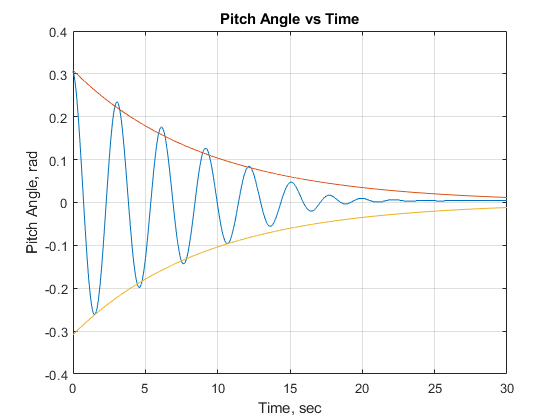


eeee = th0 * exp(-time_ii * o);
plot(time_ii,th3)
hold on 
plot(time_ii,eeee)
plot(time_ii,-eeee)
xlim([0 30])
title('Pitch Angle vs Time')
xlabel('Time, sec')
ylabel('Pitch Angle, rad')
grid on
hold off

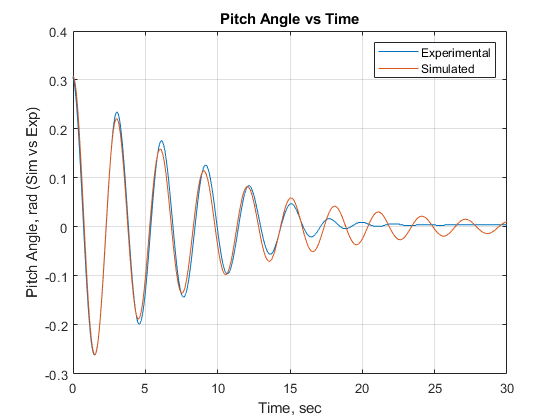



out = sim('part_iisim.slx');
thiisim = out.th.data;
timesim = out.th.time;
plot(time_ii,th3)
hold on
plot(timesim,thiisim)
xlim([0 30])
title('Pitch Angle vs Time')
xlabel('Time, sec')
ylabel('Pitch Angle, rad (Sim vs Exp)')
grid on
legend('Experimental','Simulated')
hold off

## Part iii)

Jy = Jp

Jy = 0.0425

yawratecw = sec4_i.Average_psi_dot.signals.values;
exptime = sec4_i.psi_dot.time-5.96;
t = 0:1/1000:45;
y0 = .259466;
cy = o*(Jp + Jshaft)

cy = 0.0051

simyawrate = y0 * exp(-o*t)

simyawrate =     0.2595    0.2594    0.2594    0.2594    0.2594    0.2593    0.2593    0.2593    0.2592    0.2592    0.2592    0.2592    0.2591    0.2591    0.2591    0.2590    0.2590    0.2590    0.2590    0.2589    0.2589    0.2589    0.2588    0.2588    0.2588    0.2588    0.2587    0.2587    0.2587    0.2586    0.2586    0.2586    0.2586    0.2585    0.2585    0.2585    0.2584    0.2584    0.2584    0.2584    0.2583    0.2583    0.2583    0.2583    0.2582    0.2582    0.2582    0.2581    0.2581    0.2581


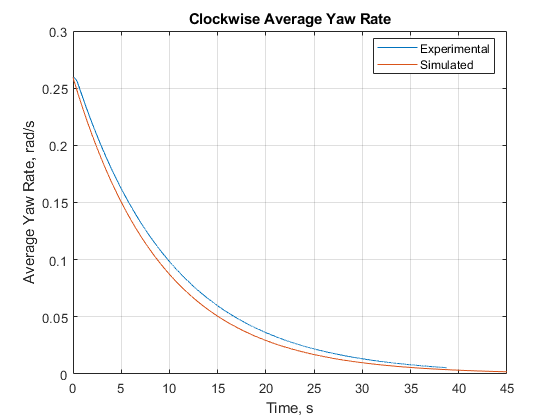

plot(exptime,yawratecw)
xlim([0 45])
hold on
grid on
title('Clockwise Average Yaw Rate')
ylabel('Average Yaw Rate, rad/s')
xlabel('Time, s')
plot(t,simyawrate)
legend('Experimental','Simulated','Location',"best")
hold off

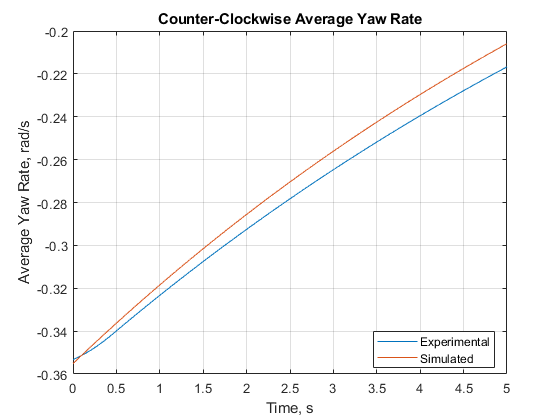




yawrateccw = sec4_ii.Average_psi_dot.signals.values;
exptime = sec4_ii.psi_dot.time-9.3480;
plot(exptime,yawrateccw)
xlim([0 5])
hold on 
y0 = -.355121;
simyawrate = y0 * exp(-o*t);
grid on
title('Counter-Clockwise Average Yaw Rate')
ylabel('Average Yaw Rate, rad/s')
xlabel('Time, s')
plot(t,simyawrate)
legend('Experimental','Simulated','Location',"best")
hold off

## Part iv:

pitchvolt = [2 3 4 5 6 7 8 9 10 11]; pitchangle = [-0.5154 -.5124 -.5032 -.481 -.4556 -.4219 -.3758 -.334 -.2608 -.111];
yawvolt = [2 3 4 5 6 7 8 9 10 11 12]; yawangle = [-.51 -.5 -.49 -.47 -.46 -.44 -.415 -.395 -.38 -.36 -.35];
l = 0.184;
pitcheqn = m*g*(h*sin(pitchangle) + Rc*cos(pitchangle));
coef = polyfit(pitchvolt,pitcheqn,1);
xp = linspace(pitchvolt(1), pitchvolt(end),2^12); yp = polyval(coef,xp);
kpp = (yp(2)-yp(1))/(xp(2)-xp(1))/l

kpp = 0.0493

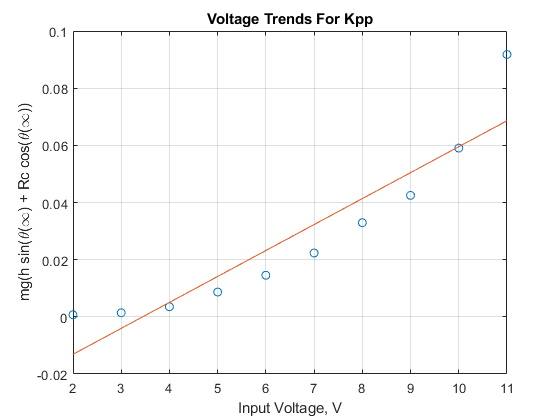


plot(pitchvolt,pitcheqn,'o')
hold on
plot(xp,yp)
grid on
xlabel('Input Voltage, V')
ylabel('mg(h sin(\theta(\infty) + Rc cos(\theta(\infty))')
title('Voltage Trends For Kpp')
hold off


yaweqn = m*g*(h*sin(yawangle) + Rc*cos(yawangle));
coef = polyfit(yawvolt,yaweqn,1);
xy = linspace(yawvolt(1),yawvolt(end),2^12); yy = polyval(coef,xp);
kpy = (yy(2)-yy(1))/(xy(2)-xy(1))

kpy = 0.0036

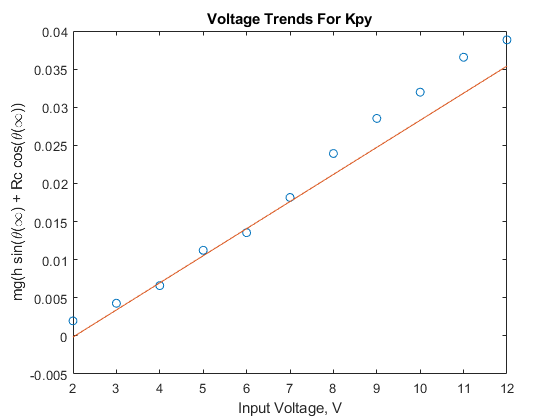

ans = 1×2 table
      pitchvolt       pitchangle  
    _____________    _____________

    [1×10 double]    [1×10 double]


ans = 1×2 table
       yawvolt         yawangle   
    _____________    _____________

    [1×11 double]    [1×11 double]



plot(yawvolt,yaweqn,'o')
hold on
plot(xy,yy)
xlabel('Input Voltage, V')
ylabel('mg(h sin(\theta(\infty) + Rc cos(\theta(\infty))')
title('Voltage Trends For Kpy')
hold off